# LABORATORIO 1.1 EJERCICIO 1

Este ejercicio se va a usar para entender los efectos del retardo que se da en la propagación de la señal de control y del retardo que se da a la hora de realimentar las señales en la señal del controlador. 

Vamos a analizar estos retardos para diferentes frecuencias de muestreo utilizando el metodo de muestreo tustin.

Como vamos a utillizar los controladores y platanas del ejemplo anterior que está en **../1.Discretización/Discretización_controladores_live**

Cs_num = [0.525,5.022,4.4]

Cs_num =     0.5250    5.0220    4.4000


Cs_den = [0.005,1,0]

Cs_den =     0.0050    1.0000         0


C= tf (Cs_num,Cs_den)

C =
 
  0.525 s^2 + 5.022 s + 4.4
  -------------------------
        0.005 s^2 + s
 
Continuous-time transfer function.
Model Properties



Gs_num= 52.1

Gs_num = 52.1000

Gs_den = [1.21,1,0]

Gs_den =     1.2100    1.0000         0


G= tf (Gs_num,Gs_den)

G =
 
      52.1
  ------------
  1.21 s^2 + s
 
Continuous-time transfer function.
Model Properties


Ahora que tenemos el controlador y el sistema vamos a discretizarlo con dos frecuencias diferentes. La primera con el rango clasico recomendado, es decir Fs1=10xBW_lazocerrado, y con el sobre muestreado, Fs2=100xBW_lazocerrado. 

Primero vamos a calcular BW_lazo cerrado para poder dar las frecuencias de muestreo. Usando estos comandos de analisis frecual:

C.InputName = 'e'; C.OutputName = 'u'; %Los mismo con C_s.u y C_s.y 
G.InputName = 'u'; G.OutputName = 'y'; %Para salida y entrada


sum = sumblk('e','r','y','+-'); % Codigo del bloque sumador en matlab
%la sintaxis es sumblk([entradas],[salidas],[signos de los operaciones a entradas])
%resultado seria sum=e+r-y

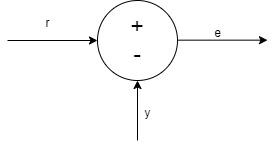

sys_CL = connect(G,C,sum, 'r','y');% El orden de los sistemas da igual si 
% están definidas las entradas y salidas de los bloques

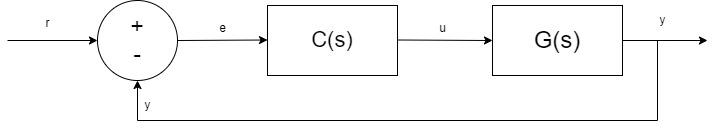

Controlled es nuestro sistema en lazo cerrado controlado. Vamos a ver sus margenes:

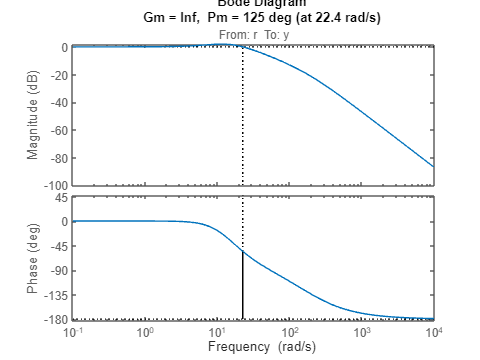

margin(sys_CL) %Nos da los margenes de F y G sobre bode

allmargin(sys_CL) %nos escribe el output para no tener que mirar

ans = struct with fields:
     GainMargin: Inf
    GMFrequency: Inf
    PhaseMargin: [-180 124.5169]
    PMFrequency: [0 22.4029]
    DelayMargin: [Inf 0.0970]
    DMFrequency: [0 22.4029]
         Stable: 1


bandwidth(sys_CL) %el dato que necesitamos.

ans = 34.1359

pole(sys_CL)

ans = 1.0e+02 *

  -1.7552 + 0.0000i
  -0.1216 + 0.0857i
  -0.1216 - 0.0857i
  -0.0097 + 0.0000i


zero(sys_CL)

ans =    -8.5901
   -0.9757


La posición de polos para analisis posteriores:

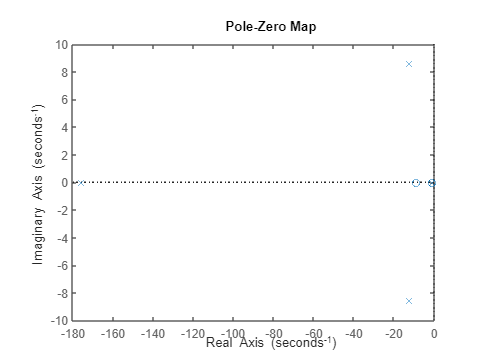

pzmap(sys_CL)

Vemos aqui que el ancho de Banda es 34.1349 rad/s. Por lo tanto las frecuencias Fs1 y Fs2 son:

Ws1 = 341.349; Ts1 =2*pi/Ws1 %s Recorcar el 2pi

Ts1 = 0.0184

Ws2 = 3413.49; Ts2= 2*pi/Ws2 %s  

Ts2 = 0.0018

________________________________________________________________

## Discretización con Ts1=0.0184

Ahora vamos a muestrear el sistema con Ts1. Para ello usaremos el comando c2d

Cz1= c2d(C, Ts1, 'tustin')

Cz1 =
 
  From input "e" to output "u":
  40.24 z^2 - 73.87 z + 33.73
  ---------------------------
    z^2 - 0.7041 z - 0.2959
 
Sample time: 0.018407 seconds
Discrete-time transfer function.
Model Properties


Para analizar esta señal de control discreta:

Polos y ceros:

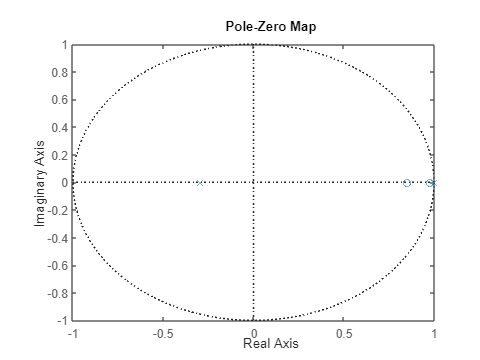

pzmap(Cz1)

polos1= pole(Cz1) %Dos polos uno en 1 y otro en -0.29 dentro del R=1 => estable

polos1 =     1.0000
   -0.2959


ceros1= zero(Cz1) %zero doble dentro de R=1 estable

ceros1 =     0.9822
    0.8535


Analisis frecuencial:

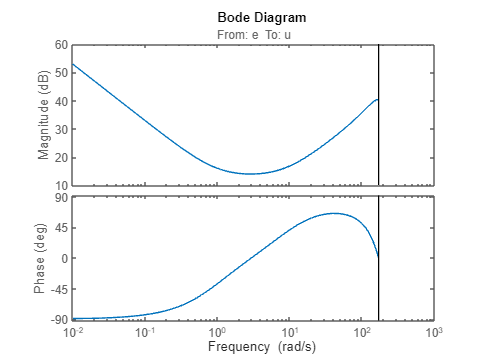

bode(Cz1) %Band refuse en gain y las frecuencias altas las desfasasa mucho

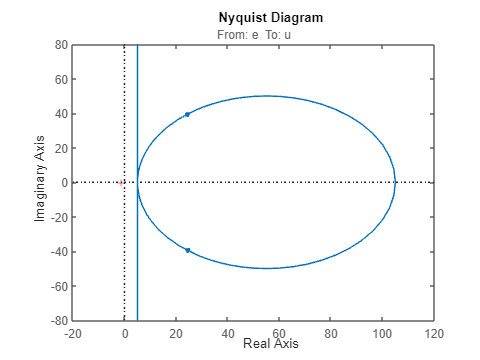

nyquist(Cz1) % N = 0 => P=Z 

## Discretización con Ts2=0.00184

Ahora vamos a muestrear el sistema con Ts2. Para ello usaremos el comando c2d

Cz2= c2d(C, Ts2, 'tustin')

Cz2 =
 
  From input "e" to output "u":
  89.46 z^2 - 177.4 z + 87.9
  --------------------------
    z^2 - 1.689 z + 0.6891
 
Sample time: 0.0018407 seconds
Discrete-time transfer function.
Model Properties


Para analizar esta señal de control discreta:

Polos y ceros:

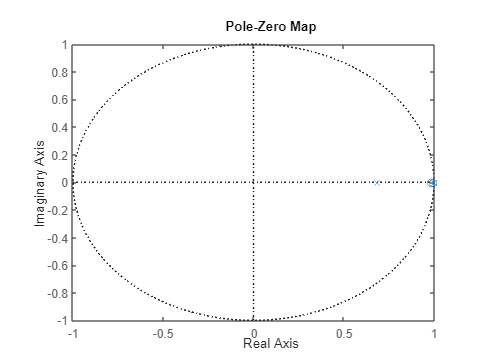

pzmap(Cz2)

polos2= pole(Cz2) %Dos polos uno en 1 y otro en 0.94 dentro del R=1 => estable pero se ha

polos2 =     1.0000
    0.6891


%movido un polo
ceros2= zero(Cz2) %zero doble dentro de R=1 estable pero se han juntado más que antes

ceros2 =     0.9982
    0.9843


bandwidth(Cz2) %Tiene sentido el error por que la ganancia en continua es infinita.

ans = NaN

Analisis frecuencial:

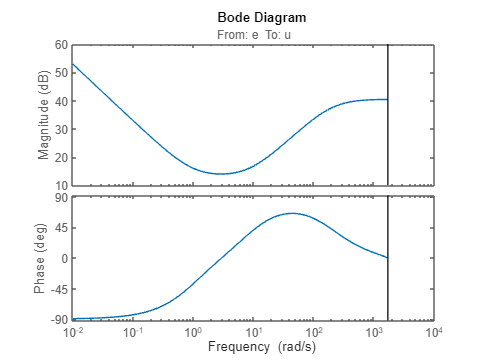


bode(Cz2) %Band refuse en gain y las frecuencias altas las desfasasa mucho

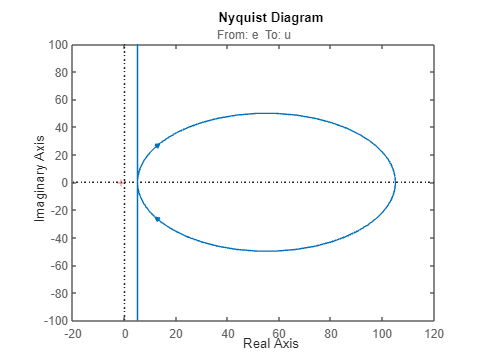

% de ha desplazado la grafica de ganancia a la DERECHA asique pue que puede que entren
% algunas fecuencias altas de más y la FASE támbien se ha desplazado un poco
nyquist(Cz2) % N = 0 => P=Z igual

### Periodo de muestreo ultracorto Ts3 = 0,000184

Por último vamos dar un periodo de muestro ultracorto el cual es un orden de magnitud menor que Ts2

Ts3= Ts2/10

Ts3 = 1.8407e-04

Ahora vamos a muestrear el sistema con Ts1. Para ello usaremos el comando c2d

Cz3= c2d(C, Ts3, 'tustin')

Cz3 =
 
  From input "e" to output "u":
  103.2 z^2 - 206.2 z + 103
  -------------------------
   z^2 - 1.964 z + 0.9639
 
Sample time: 0.00018407 seconds
Discrete-time transfer function.
Model Properties


Para analizar esta señal de control discreta:

Polos y ceros:

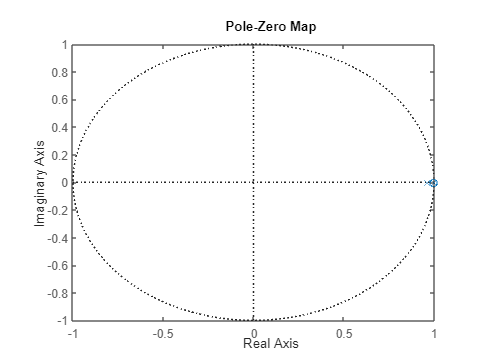

pzmap(Cz3)

polos3= pole(Cz3) %Se han juntado todos los polos y cero en +1

polos3 =     1.0000
    0.9639


ceros3= zero(Cz3) 

ceros3 =     0.9998
    0.9984


Analisis frecuencial:

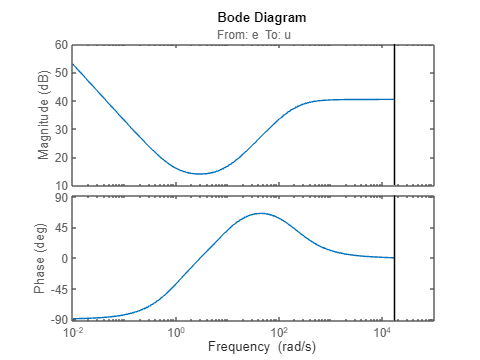

bode(Cz3) %Band refuse en gain y las frecuencias altas las desfasasa mucho

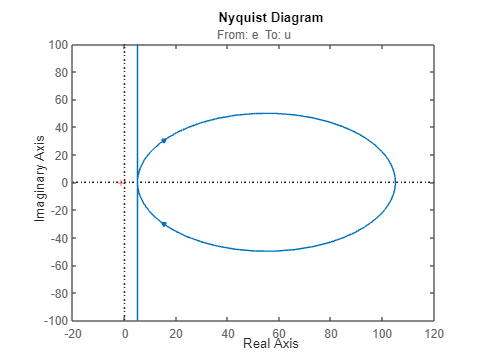

% de ha desplazado la grafica de ganancia a la IZQUIERDA asique pue que puede que entren
% algunas fecuencias BAJAS de más y la FASE támbien se ha desplazado un poco
nyquist(Cz3) % N = 0 => P=Z igual


a1=Cz2.den{1,1}(2)

a1 = -1.6891

a2=Cz2.den{1,1}(3)

a2 = 0.6891


b0=Cz2.num{1,1}(1)

b0 = 89.4586

b1=Cz2.num{1,1}(2)

b1 = -177.3532

b2=Cz2.num{1,1}(3)

b2 = 87.8972